*Use the Live Editor to ****edit**** and ****run**** this live script in your browser or *[*download*](https://www.mathworks.com/live_editor_sunrisesunset)* and run it in your MATLAB.*

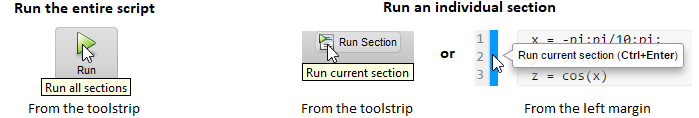

***Challenge:**** Can you find the sunrise and sunset times for your location?*

# Estimating Sunrise and Sunset

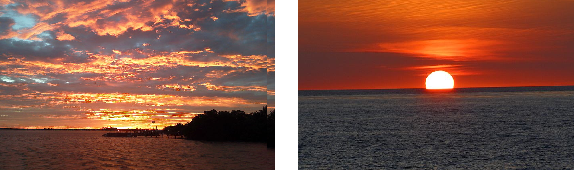

Estimate sunrise and sunset times for a given longitude and latitude.  Offset from Greenwich Mean Time is estimated using time zone shape files from [https://github.com/evansiroky/timezone-boundary-builder.](https://github.com/evansiroky/timezone-boundary-builder.)  

load timeZones.mat

Using the  latitude ($\phi$), the sun's declination ($\delta$) and the solar time correction ($SC$) we can calculate sunrise and sunset times.


$$\mbox{sunrise} = 12 - \frac{\cos^{-1}\left(-\tan\phi\tan\delta\right)}{15^\circ} 
- \frac{SC}{60}\qquad\qquad\mbox{sunset} = 12 + \frac{\cos^{-1}\left(-\tan\phi\tan\delta\right)}{15^\circ} 
- \frac{SC}{60}$$


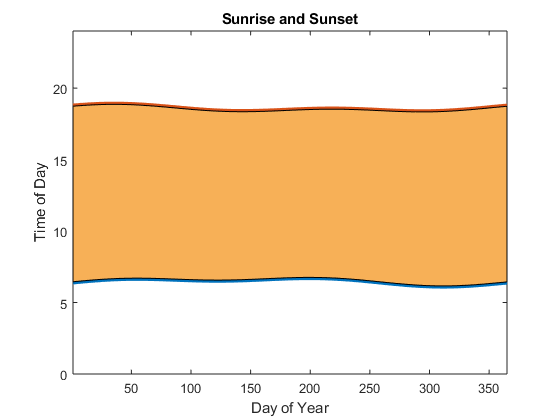

longitude =-53;      
latitude  = -5;       

days = 1:365;
UTCoff = findOffset(timeZones,longitude,latitude);
eotCorr = equationOfTime(days);
solarCorr = 4*(longitude - 15*UTCoff) + eotCorr;
delta = asind(sind(23.45)*sind(360*(days - 81)/365));
sunrise = 12 - acosd(-tand(latitude)*tand(delta))/15 - solarCorr/60;
sunset  = 12 + acosd(-tand(latitude)*tand(delta))/15 - solarCorr/60;

clf ; plot(days, sunrise, days, sunset, 'LineWidth', 4)
axis([1 365 0 24])
title('Sunrise and Sunset')
xlabel('Day of Year') ; ylabel('Time of Day')
hold on
patch([days flip(days)], [sunrise flip(sunset)], [0.97 0.69 0.34])

## Helper Functions

function eot = equationOfTime(range)

B = 360*(range - 81)/365;
eot = 9.87*sind(2*B) - 7.53*cosd(B) - 1.5*sind(B);

end

 
function offset = findOffset(timeZones, longitude, latitude)

test = zeros(size(timeZones,1),1);
for i = 1:size(timeZones,1) 
    test(i) = inpolygon(longitude, latitude, timeZones(i).X,timeZones(i).Y) ; 
end
idx = find(test,1);
tz = timeZones(idx).tzid;
offset = hour(datetime(datestr(now),'TimeZone','Europe/London') - ...
    datetime(datestr(now),'TimeZone',tz));

end